clear all;
clc;

% --------------------------------------------------%
% Forward Kinematics Calculator
% Gets transform from End-effector to base (T0_ee)
%---------------------------------------------------%

syms theta1 theta2 theta3 real
syms a1 a2 a3 real

% DH parameters
% Each element is for a particular transform from a joint frame {i-1} to
% {i}
alpha = [0 0 0]

alpha =      0     0     0


a = [0 a1 a2]

$$a = \left(\begin{array}{ccc} 0 & a_{1} & a_{2} \end{array}\right)$$

d = [0 0 0]

d =      0     0     0


theta = [theta1 theta2 0]

$$theta = \left(\begin{array}{ccc} \theta_{1} & \theta_{2} & 0 \end{array}\right)$$


% Parameter ranges
a1_range = 2;
a2_range = a1_range/2;
theta1_range = arr2Rad(linspace(0,180, 180/2));

out =          0    0.0353    0.0706    0.1059    0.1412    0.1765    0.2118    0.2471    0.2824    0.3177    0.3530    0.3883    0.4236    0.4589    0.4942    0.5295    0.5648    0.6001    0.6354    0.6707    0.7060    0.7413    0.7766    0.8119    0.8472    0.8825    0.9178    0.9531    0.9884    1.0237    1.0590    1.0943    1.1296    1.1649    1.2002    1.2355    1.2708    1.3061    1.3414    1.3767    1.4120    1.4473    1.4825    1.5178    1.5531    1.5884    1.6237    1.6590    1.6943    1.7296


theta2_range = arr2Rad(linspace(-90,180, 270/2));

out =    -1.5708   -1.5356   -1.5005   -1.4653   -1.4301   -1.3950   -1.3598   -1.3246   -1.2895   -1.2543   -1.2191   -1.1840   -1.1488   -1.1136   -1.0785   -1.0433   -1.0081   -0.9730   -0.9378   -0.9026   -0.8675   -0.8323   -0.7971   -0.7620   -0.7268   -0.6916   -0.6565   -0.6213   -0.5861   -0.5510   -0.5158   -0.4806   -0.4454   -0.4103   -0.3751   -0.3399   -0.3048   -0.2696   -0.2344   -0.1993   -0.1641   -0.1289   -0.0938   -0.0586   -0.0234    0.0117    0.0469    0.0821    0.1172    0.1524



[theta1_grid, theta2_grid] = ndgrid(theta1_range, theta2_range);

% Create arrays of every possible value tuple
theta1_vals = reshape(theta1_grid, 1, []);
theta2_vals = reshape(theta2_grid, 1, []);

% Create identity matrix for multiplication
T0_ee = eye(4)

T0_ee =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1



% Apply each transformation
for i = 1:length(alpha)
    T{i} = TF(a(i),alpha(i),d(i),theta(i));
    T0_ee = T0_ee*T{i};
end

% Yields output 
disp('Symbolic output')

Symbolic output


T0_ee

$$T0\_ee = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & 0 & a_{2}\,\sigma_{1}+a_{1}\,\cos\left(\theta_{1}\right)\\ \sigma_{2} & \sigma_{1} & 0 & a_{2}\,\sigma_{2}+a_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{2}=\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) \end{array}$$


% Have Matlab simplify
disp('Simplified Symbolic output')

Simplified Symbolic output


Ts = simplify(T0_ee)

$$Ts = \left(\begin{array}{cccc} \cos\left(\theta_{1}+\theta_{2}\right) & -\sin\left(\theta_{1}+\theta_{2}\right) & 0 & a_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\cos\left(\theta_{1}\right)\\ \sin\left(\theta_{1}+\theta_{2}\right) & \cos\left(\theta_{1}+\theta_{2}\right) & 0 & a_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+a_{1}\,\sin\left(\theta_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Replace symbols with real values for a result
disp('Symbolic output with real values')

Symbolic output with real values


x = T0_ee(1,4)

$$x = a_{2}\,\left(\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\right)+a_{1}\,\cos\left(\theta_{1}\right)$$

y = T0_ee(2,4)

$$y = a_{2}\,\left(\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)+\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\right)+a_{1}\,\sin\left(\theta_{1}\right)$$

z = T0_ee(3,4)

$$z = 0$$


% Sanity-check. We use a near-zero threshold as there are always precision
% errors in floating point operations
if ~any(arrayfun(@(i) isAlways(abs(i)<0.0001),[x y z]))
    error('At least one position needs to be 0 in the 2D case')
end

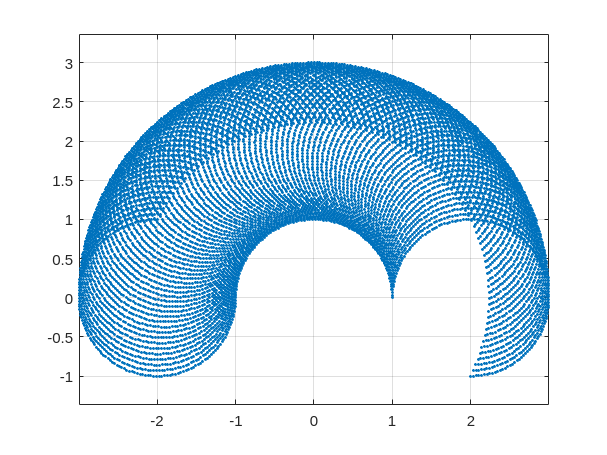


% Convert from symbolic to numerical functions for faster evaluation
x_func = matlabFunction(x);
y_func = matlabFunction(y);
z_func = matlabFunction(z);

% Calculate positions
x_out = x_func(a1_range, a2_range, theta1_vals, theta2_vals);
y_out = y_func(a1_range, a2_range, theta1_vals, theta2_vals);

% Plot
figure(1)
plot(x_out,y_out,'.')
axis equal
grid on

function out = arr2Rad(A)
    out = arrayfun(@(angle) deg2rad(angle), A)
end
function T = TF(a,alpha,d,theta)
% Generic link transform function that generates a homogeneous transform
% matrix from the DH parameters.
T = [cos(theta) -sin(theta) 0 a
     sin(theta)*cos(alpha) cos(theta)*cos(alpha) -sin(alpha) -sin(alpha)*d
     sin(theta)*sin(alpha) cos(theta)*sin(alpha)  cos(alpha)  cos(alpha)*d
     0 0 0 1];
end